# Validate your conclusions by running equivalent Python code (using the MATLAB Live Task for Python)

**Task: Use K-means with 50 clusters and K-means++ initialization**

This example requires to have Scikit-Learn and Scipy installed in your Python environment

## Data Generation

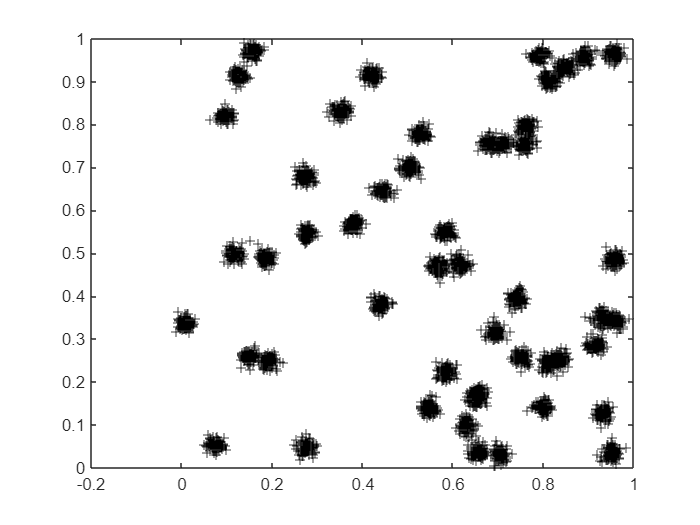

rng("default")
bounds = [0 1; 0 1];   % Cluster centers to be in these bounds.
nclust = 50;           % This many clusters.
points = 100;          % Number of points in each cluster.
std_dev = 0.01;        % Standard deviation of each cluster.

data = dataGeneration(bounds,nclust,points,std_dev);

plot(data(:,1), data(:,2), '+k')

What follows is a demonstration that different algorithm implementations can lead to different results.

## Clustering in MATLAB

[~, matlab_centroids] = kmeans(data, nclust); % kmeans uses kmeans++ initialization by default

## Clustering in Python

nclust = uint8(nclust);

% Running Python statements from Live Task
pythonCode = [
    "# Data conversion"
    "import numpy as np"
    "data = np.array(data)"
    "# Using Scikit-learn"
    "from sklearn.cluster import KMeans as scikit_kmeans"
    "kmeans_scikit_res = scikit_kmeans(n_clusters=nclust,init='k-means++').fit(data)"
    "scikit_centroids = kmeans_scikit_res.cluster_centers_"
    "# Using Scipy"
    "import scipy.cluster"
    "scipy_res = scipy.cluster.vq.kmeans2(data,k=nclust,minit='++')"
    "scipy_centroids = scipy_res[0]"
    ];
[scikit_centroids, scipy_centroids] = pyrun(pythonCode, ["scikit_centroids", "scipy_centroids"], "data", data, "nclust", nclust);

class(scikit_centroids)

ans = 'py.numpy.ndarray'

class(scipy_centroids)

ans = 'py.numpy.ndarray'

% Data conversion from numpy array to MATLAB double
scikit_centroids = double(scikit_centroids);
scipy_centroids = double(scipy_centroids);

## Compare results

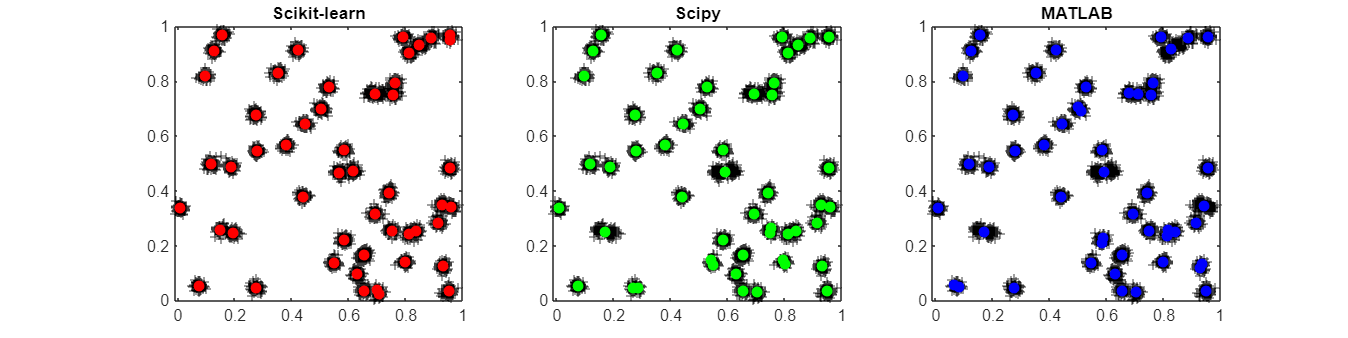

figure("Position", [600 600 1200 300])
subplot(1,3,1)
plot(data(:,1),data(:,2),"+k")
hold on
plot(scikit_centroids(:,1), scikit_centroids(:,2), "or", "MarkerFaceColor", "r")
title("Scikit-learn")
hold off
subplot(1,3,2)
plot(data(:,1),data(:,2),"+k")
hold on
plot(scipy_centroids(:,1), scipy_centroids(:,2), "og", "MarkerFaceColor", "g")
title("Scipy")
hold off
subplot(1,3,3)
plot(data(:,1),data(:,2),"+k")
hold on
plot(matlab_centroids(:,1), matlab_centroids(:,2), "ob", "MarkerFaceColor", "b")
title("MATLAB")
hold off

All implementations are correct. 

Each implementation is simply giving a local optima of the optimization problem through different initial points selected randomly.

It is important to validate your conclusions. And always share both code and data!

function [v, vcentroid, my_proportion, my_group] = dataGeneration(x,c,n,d)

    if nargin < 3 
        error('Not enough input arguments')
    end
    if nargin == 3
        d = 1;
    end

    [r,~] = size(x);
    minv = min(x,[],2);
    maxv = max(x,[],2);
    vcentroid = rand(r,c) .* ((maxv-minv) * ones(1,c)) + (minv * ones(1,c));
    t = c*n;
    v = repmat(vcentroid,1,n) + randn(r,t)*d;
    v = v';
    vcentroid = vcentroid';

    if nargout > 2
        my_proportion = repmat(n,1,c);
        my_group = strcat({'Group_'},num2str((1:c)','%-d'));
        my_group = repmat(my_group',1,n);
    end
    
end

*© 2022, The MathWorks, Inc.*